# Analysis of ERG data obtained from SMH

## add path to where your codes are

addpath(genpath('\codes'))

## STEP1 SET Variables to be adjusted for the recording

set data path

data_path='Z:\Inyoung\IJ_Ephysetup\ERG_data\'; %folder where data for experiment is found

set path of excel sheet

table_path = dir(fullfile(data_path,'*masterfile_smh*')); % information table about the experiments
T = readtable(fullfile(data_path,table_path(1).name));
warning off

set some variables

cfg.sample_rate = 10000;

cfg.stim_initiation = 5*cfg.sample_rate; %time at which the stim protocol starts
cfg.stim_duration = 1; %in seconds - 0.01 = 10 ms
cfg.ISI = 5; %inter stimulus interval = 2.5s.
cfg.n_pulse = 10; %number of light pulses
cfg.Mutcolor='m';


select trial number to be plotted if ERG were measured multiple time

BestTrial_Y_1_N_2_=1;

## STEP2 COLLECT data from control

BestTrial_Y_1_N_2_

BestTrial_Y_1_N_2_ = 1

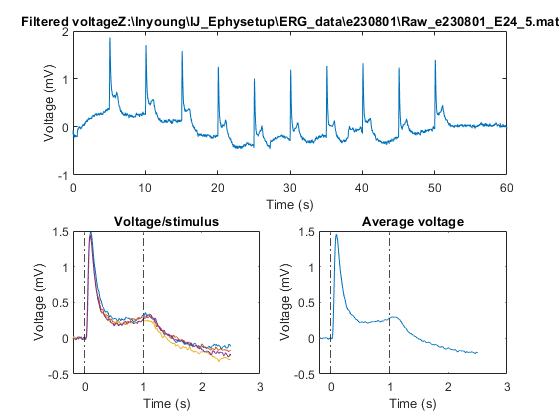

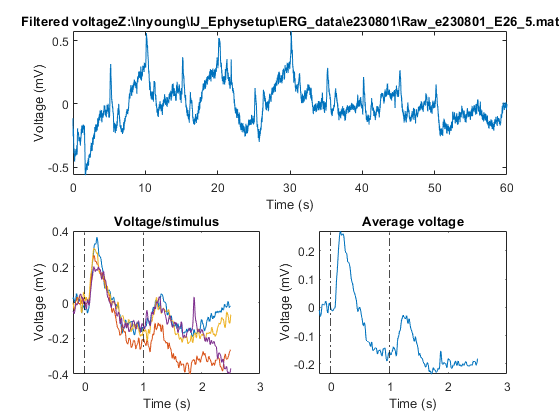

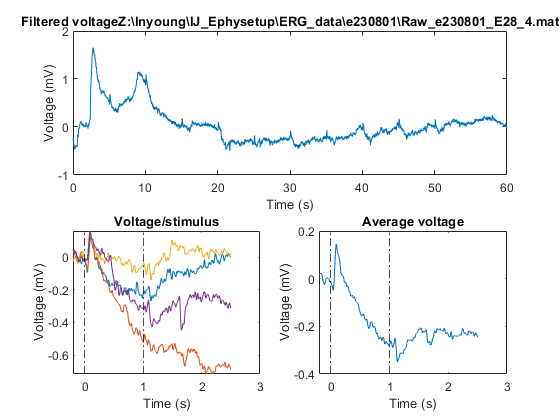

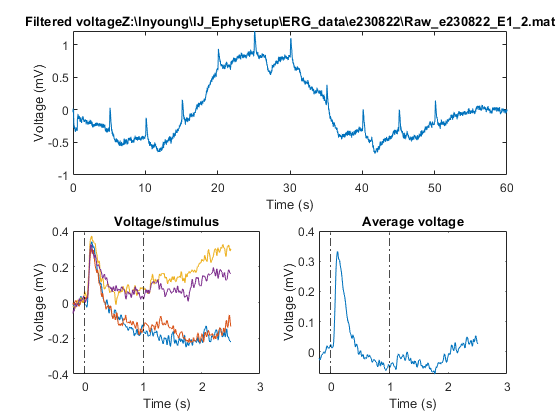

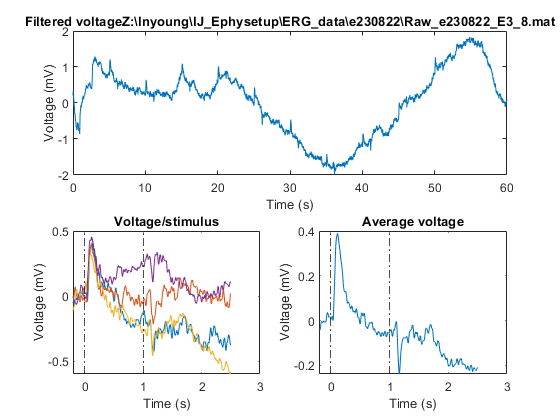

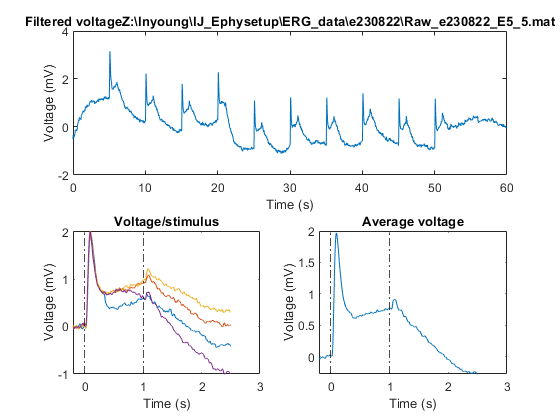

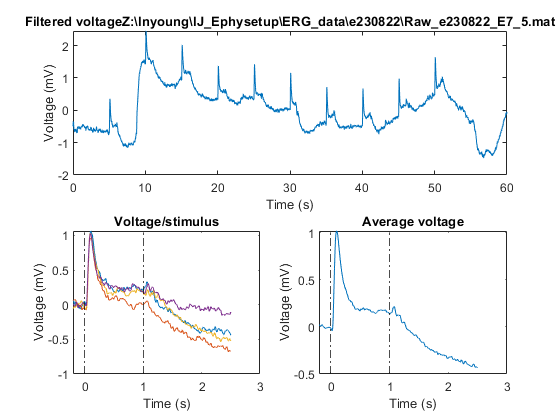

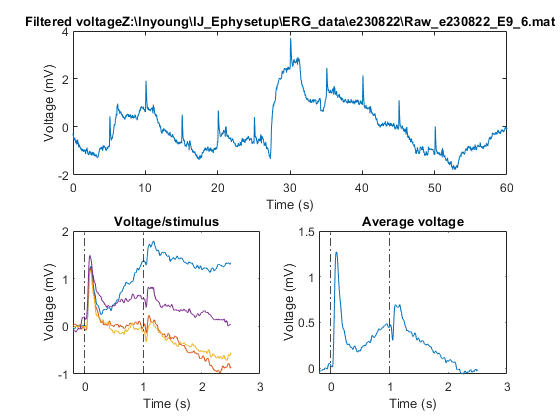


Genotype=1; % genotype 1 is control
groupID=find(T.Response_Y_1_N_2_>0 & T.Genotype_control_1_Mutant_2_==Genotype & T.BestTrial_Y_1_N_2_==BestTrial_Y_1_N_2_);

for i=1:length(groupID)
path=strcat(data_path,T.FolderName(groupID(i)),'\');
toload = ['*' cell2mat(T.FileName(groupID(i))) '*'];
toload_path = dir(fullfile(path{1, 1},toload));
cfg.name = [toload_path.folder filesep toload_path.name];
[data]=load(cfg.name);
voltage = data.voltage;
[v_mean]=plot_ERG (voltage,cfg);
warning off
V_perfish.control(i,:) = v_mean;
end

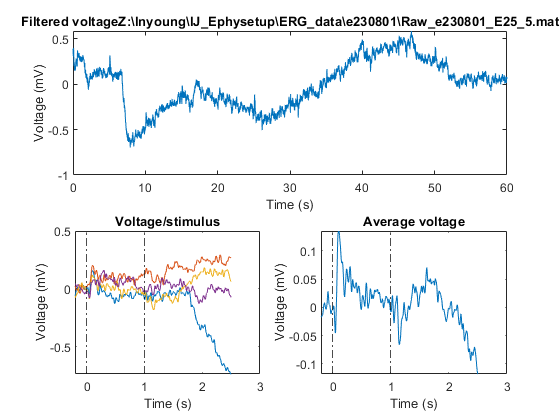

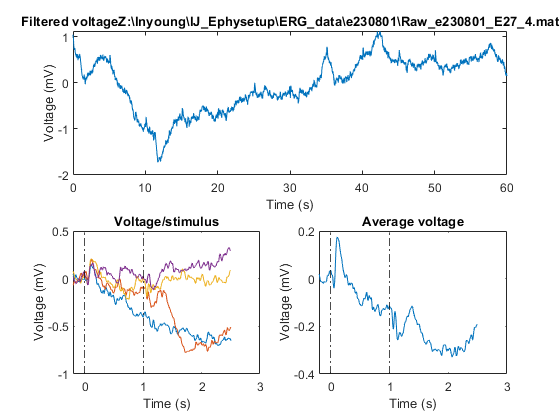

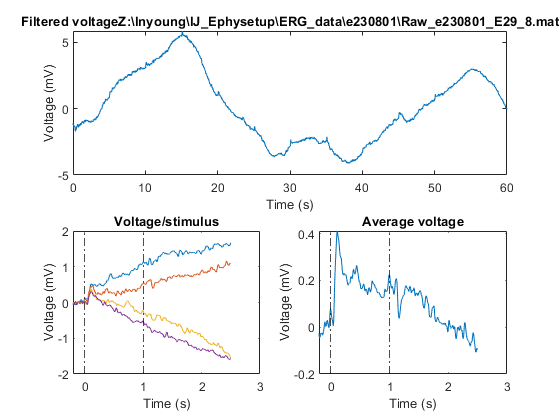

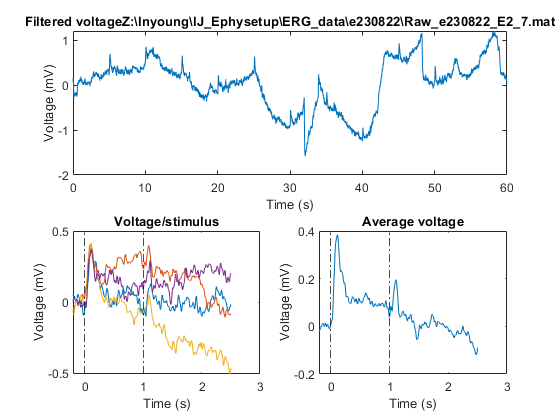

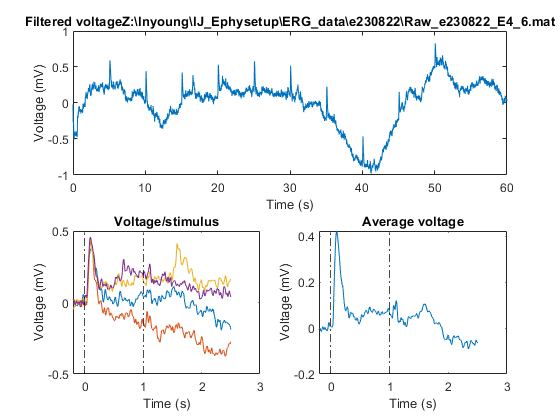

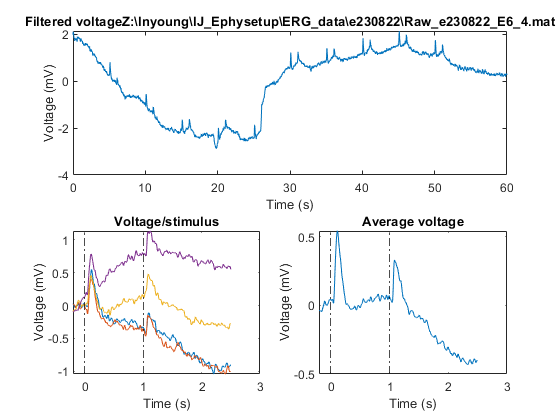

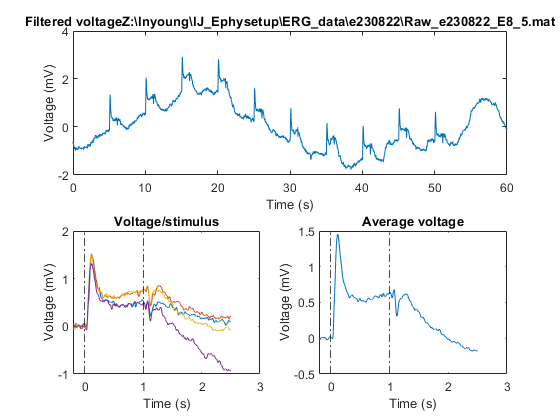

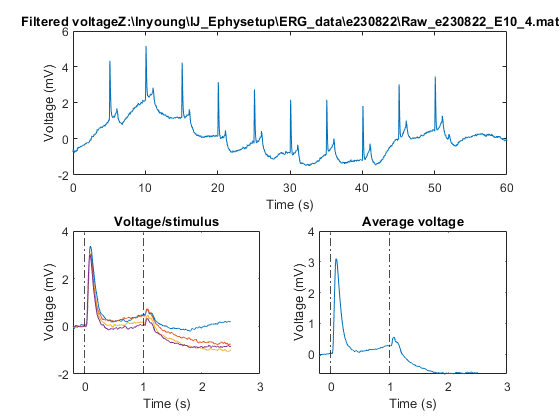


Genotype=2; % genotype 2 is mutant
groupID=find(T.Response_Y_1_N_2_>0 & T.Genotype_control_1_Mutant_2_==Genotype & T.BestTrial_Y_1_N_2_==BestTrial_Y_1_N_2_);

for i=1:length(groupID)
path=strcat(data_path,T.FolderName(groupID(i)),'\');
toload = ['*' cell2mat(T.FileName(groupID(i))) '*'];
toload_path = dir(fullfile(path{1, 1},toload));
cfg.name = [toload_path.folder filesep toload_path.name];
[data]=load(cfg.name);
voltage = data.voltage;
[v_mean]=plot_ERG (voltage,cfg);
V_perfish.mutant(i,:) = v_mean;
end

## PLOT THE AVERAGE RESPONSE

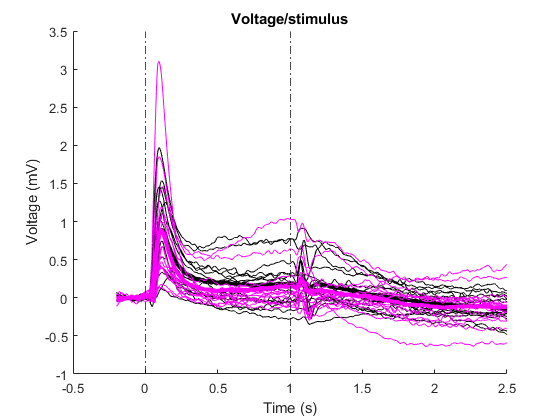

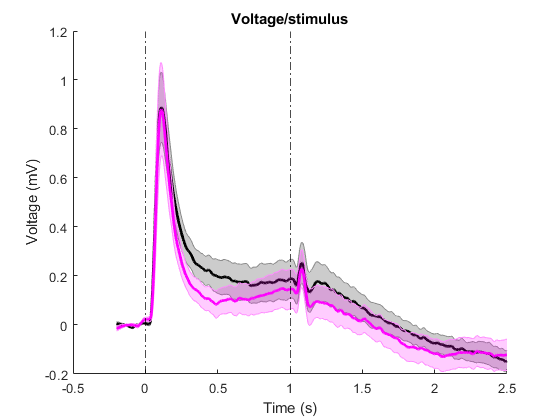

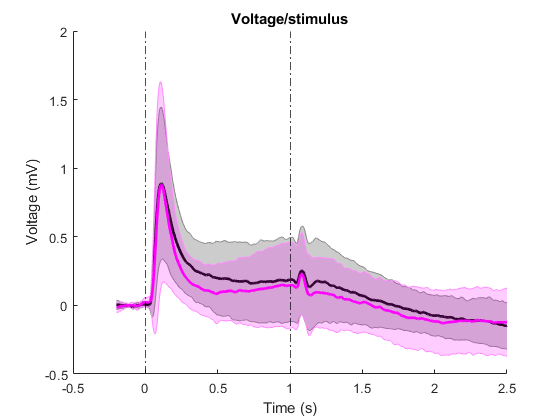

plot_average(V_perfish,cfg)

## Plot quantification and statistical analysis

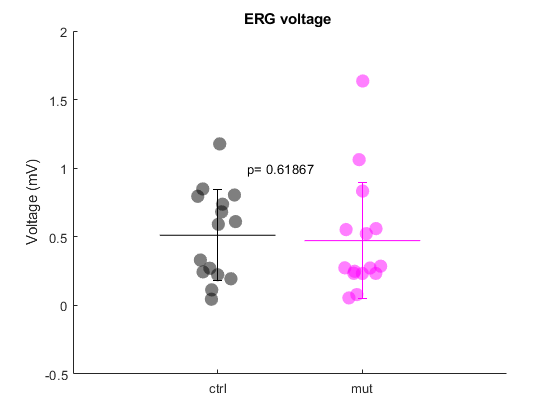

range=[2000:4000]; %200ms=lightON and stimulus for 200ms
% Calculate the means for the specified range (2000:4000)
mean_control = mean(V_perfish.control(:, range), 2);           % Mean along rows
std_control = std(mean(V_perfish.control(:, range)), 0, 2);    % Standard deviation along rows
mean_mutant = mean(V_perfish.mutant(:, range), 2);             % Mean along rows
std_mutant = std(mean(V_perfish.mutant(:, range)), 0, 2);      % Standard deviation along rows

% Perform ranksum test
[p_value, h, stats] = ranksum(mean_control, mean_mutant);


figure, 
toplotC=mean_control;
toplotM=mean_mutant;
swarmchart(ones(size(toplotC,1),1), toplotC,100,'k','filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
line([0.6 1.4], repmat(mean(toplotC),1,2),'Color','k')
errorbar(1,mean(toplotC), std(toplotC),'Color','k')
swarmchart(2*ones(size(toplotM,1),1), toplotM,100,cfg.Mutcolor,'filled','MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5,'XJitterWidth',0.3), hold on
line([1.6 2.4], repmat(mean(toplotM),1,2),'Color',cfg.Mutcolor)
errorbar(2,mean(toplotM), std(toplotM),'Color',cfg.Mutcolor)
xlim([0 3]),ylim([-0.5 2])
ylabel('Voltage (mV)')
text(1.2,1,['p= '...
    num2str(ranksum(toplotC,toplotM))])
xticks([1 2])
xticklabels({'ctrl','mut'})
title('ERG voltage ' )

clear toplotC toplotM


## Nested functions

function [v_mean]=plot_ERG (voltage,cfg)

% filtering the voltage trace----------------------------------
% cutoff frequency for low pass filter (i.e., anything above this frequency is "removed")
cutoff=100; 
filt_voltage=EY_LP_bw_Filt(voltage,cutoff);
% high pass filter with cutoff of 0.01 (i.e., anything below this frequency is "removed")
filt_voltage=highpass(filt_voltage,0.01,cfg.sample_rate);

% Make a time vector for the recording ------------------------------
time_end=size(voltage,1)/cfg.sample_rate;
time=0:time_end/size(voltage,1):time_end;
time=time(1:end-1)';

% Establishing the stimulus train onset times
stim_onset=nan(cfg.n_pulse,1);
stim_onset(1)=cfg.stim_initiation;
for i=2:cfg.n_pulse
    stim_onset(i)=stim_onset(i-1)+(cfg.ISI)*cfg.sample_rate;
end

%Finding the voltage for stim onset times
response_time=(cfg.ISI/2)*cfg.sample_rate; % duration to be plotted
baseline_time=0.2*cfg.sample_rate; % baseline to be plotted
temp_voltage=[];
 for x=1:4 % analyse the first 4 stimuli
    temp_voltage(:,x)=[filt_voltage(stim_onset(x)-baseline_time:stim_onset(x)+response_time,:)]-mean(filt_voltage(stim_onset(x)-baseline_time:stim_onset(x)-1)); %normalized so that baseline is equal to 0
 end

%Calculating the mean voltage 
v_mean=mean((temp_voltage),2);

%Finding the time (in s) of the stimulus onsets
time_end_mean=size(v_mean,1)/cfg.sample_rate;
time_mean=0:time_end_mean/size(v_mean,1):time_end_mean;
time_mean=(-baseline_time/cfg.sample_rate+time_mean(1:end-1))';


% Plotting the figure of the filtered membrane potential trace
figure();
subplot(2,2,1:2)
plot(time,filt_voltage);
xlabel('Time (s)');
ylabel('Voltage (mV)');
title(['Filtered voltage' cfg.name]);

subplot(2,2,3)
for i=1:4%10
plot(time_mean,(temp_voltage(:,i))), hold on
end
xline(0,'-.k');
xline(cfg.stim_duration,'-.k');
xlabel('Time (s)');
ylabel('Voltage (mV)');
title('Voltage/stimulus');

subplot(2,2,4)
plot(time_mean,v_mean);
% hold on
% plot(time_mean,filt_v_mean);
xline(0,'-.k');
xline(cfg.stim_duration,'-.k');
xlabel('Time (s)')
ylabel('Voltage (mV)')
title('Average voltage');

%saveas(gcf, [erase(cfg.name,'.mat') '.png'])

end


function plot_average(V_perfish,cfg)
% baseline duration
baseline_time=0.2*cfg.sample_rate; % baseline to be plotted
%Finding the time (in s) of the stimulus onsets
time_end_mean=size(V_perfish.control,2)/cfg.sample_rate;
time_mean=0:time_end_mean/size(V_perfish.control,2):time_end_mean;
time_mean=(-baseline_time/cfg.sample_rate+time_mean(1:end-1))';


figure, 
for i=1:size(V_perfish.control,1)
plot(time_mean,(V_perfish.control(i,:)),'Color', 'k','LineWidth',0.5), 
hold on
end
plot(time_mean,mean(V_perfish.control,1),'k','LineWidth',3),
for i=1:size(V_perfish.mutant,1)
plot(time_mean,(V_perfish.mutant(i,:)),'Color',cfg.Mutcolor,'LineWidth',0.5)
alpha(.5)
hold on
end
plot(time_mean,mean(V_perfish.mutant,1),cfg.Mutcolor,'LineWidth',3),
%xlim([-0.2 1.2]), ylim([-0.5 3]);
xline(0,'-.k');
xline(cfg.stim_duration,'-.k');
xlabel('Time (s)');
ylabel('Voltage (mV)');
title(['Voltage/stimulus']);
box off;

figure, 
shadedErrorBar(time_mean,mean(V_perfish.control,1),std(V_perfish.control,[],1)/sqrt(size(V_perfish.control,1)),'lineprops','k'),
hold on
shadedErrorBar(time_mean,mean(V_perfish.mutant,1),std(V_perfish.mutant,[],1)/sqrt(size(V_perfish.mutant,1)),'lineprops',cfg.Mutcolor),
%xlim([-0.2 1.2]), ylim([-0.5 1.2]);
xline(0,'-.k');
xline(cfg.stim_duration,'-.k');
xlabel('Time (s)');
ylabel('Voltage (mV)');
title(['Voltage/stimulus']);
box off;

figure, 
shadedErrorBar(time_mean,mean(V_perfish.control,1),std(V_perfish.control,[],1),'lineprops','k'),
hold on
shadedErrorBar(time_mean,mean(V_perfish.mutant,1),std(V_perfish.mutant,[],1),'lineprops',cfg.Mutcolor),
%xlim([-0.2 1.2]), ylim([-0.5 1.2]);
xline(0,'-.k');
xline(cfg.stim_duration,'-.k');
xlabel('Time (s)');
ylabel('Voltage (mV)');
title(['Voltage/stimulus']);
box off;

end